%plot 2 lab 5

% Also include a plot showing the common-source node voltage, V , as a function of
% V1 − V2 for all three values of V2.

load('0.7V_bias_below_threshold\2.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\2.5V gate\Source\Vsource.mat')

V1_minus_V2_2V = Vgate; 
Vcm_2V = Vsource; 

load('0.7V_bias_below_threshold\3.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\3.5V gate\Source\Vsource.mat')

V1_minus_V2_3V = Vgate; 
Vcm_3V = Vsource; 

load('0.7V_bias_below_threshold\4.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\4.5V gate\Source\Vsource.mat')

V1_minus_V2_4V = Vgate; 
Vcm_4V = Vsource;


plot(V1_minus_V2_2V, Vcm_2V, '.')
hold on 
plot(V1_minus_V2_3V, Vcm_3V, '.')
plot(V1_minus_V2_4V, Vcm_4V, '.')
grid on
title("Differential Input Voltage Versus Common Node Voltage")
xlabel("$V_{1} - V_{2}$ ($V$)", "Interpreter", "latex")
ylabel("Common Node Voltage ($V$)", "Interpreter", "latex")
leg = legend("$2.5V$", "$3.5V$", "$4.5V$", "Interpreter", "latex")

leg =   Legend ($2.5V$, $3.5V$, $4.5V$) with properties:

         String: {'$2.5V$'  '$3.5V$'  '$4.5V$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7506 0.7860 0.1357 0.1148]
          Units: 'normalized'

  Show all properties


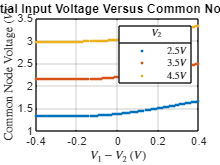

title(leg, "$V_{2}$", "Interpreter", "latex")
hold off;